clear;
clc;

numRx = 4;
numADCSamples = 200;
filestr = './static/3times_1.bin'; 
  
data = read1843Data(filestr, numADCSamples, numRx);

numFrame = 200;
numChirp = size(data,2)/numADCSamples;
numChirpPerFrame = numChirp/numFrame; 

targRx = 1;
targData = data(targRx,:);
targData = reshape(targData, numADCSamples, numChirpPerFrame, []);
disp(size(targData))

   200   128   200




% rangeWin = hamming(numADCSamples);
% rangeResult = targData .* repmat(rangeWin, 1, size(targData,2));
rangeResult = fftshift(fft(targData, [], 1), 1);
rangeResult = reshape(rangeResult, numADCSamples, []);
disp(size(rangeResult))

         200       25600



c = 3e8;
S = 29.982e12;
fs = 10000e3;

rangeRes = (c*fs) / (2*S*numADCSamples);
rangeTicks = rangeRes .* ((-numADCSamples/2):(numADCSamples/2-1));
rangeTicks = round(rangeTicks,2);

disp(rangeRes)

    0.2502



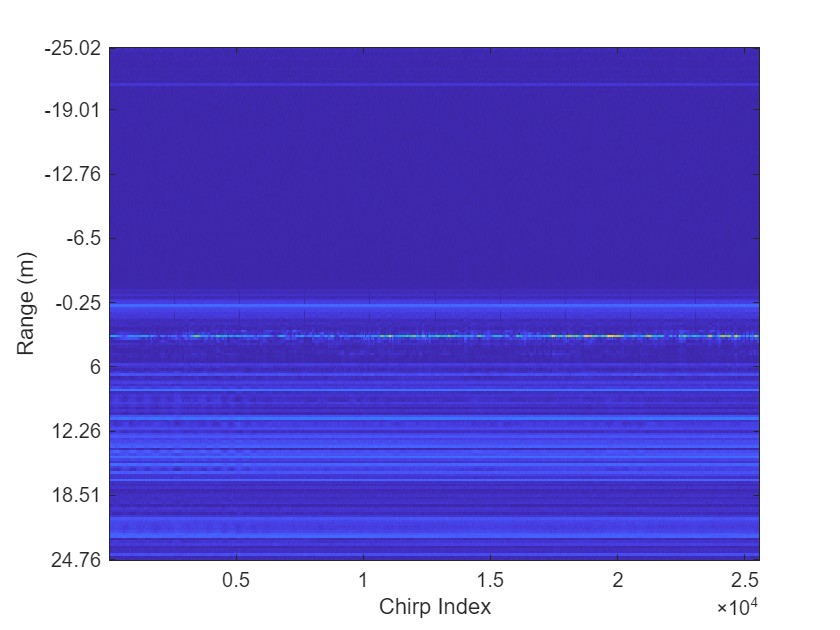


figure(1);
imagesc(abs(rangeResult));

yidxs = floor(linspace(1,length(rangeTicks),9));
yticks(yidxs);
yticklabels(string(rangeTicks(yidxs)))
xlabel('Chirp Index');
ylabel('Range (m)');

targBin = 111;

rangeFFTResult = rangeResult(targBin, :);
phases = angle(rangeFFTResult);

cur = phases(1);
displacement = zeros(1, numChirp);
displacement(1) = 0;

for i = 2:numChirp
    if abs(phases(i - 1) - phases(i)) < pi
        displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1);
    elseif phases(i - 1) > phases(i)
        displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1) + 2 * pi;
    else
        displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1) - 2 * pi;
    end
end
displacement = displacement .* (c / 4 / pi / 77e9) * (1 / .192)

displacement =          0    0.0008    0.0011    0.0009    0.0010    0.0016    0.0016    0.0016    0.0021    0.0020    0.0027    0.0014    0.0022    0.0017    0.0017    0.0024    0.0018    0.0019    0.0014    0.0019    0.0015    0.0016    0.0016    0.0015    0.0010    0.0017    0.0024    0.0012    0.0024    0.0016    0.0015    0.0026    0.0016    0.0013    0.0021    0.0018    0.0020    0.0018    0.0020    0.0015    0.0018    0.0017    0.0016    0.0020    0.0020    0.0019    0.0020    0.0023    0.0016    0.0018


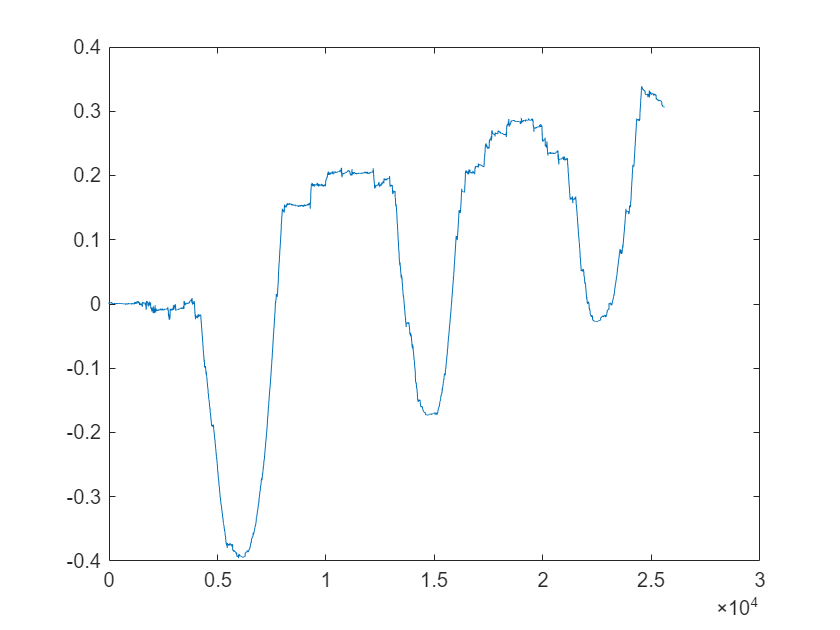

figure(8);
xlabel('Chirp Index');
ylabel('Displacement (m)');
plot(1:numChirp, displacement)

targFrame = 40;

dopplerWin = hamming(numChirpPerFrame).';
dopplerResult = rangeResult(:,(targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));
dopplerResult = dopplerResult .* repmddat(dopplerWin, numADCSamples, 1);

函数或变量 'repmddat' 无法识别。

dopplerResult = fftshift(fft(dopplerResult, numChirpPerFrame, 2),2);

fc = 77e9;
Tc = 210e-6;
lambda = c / fc;

vecRes = lambda / (2*numChirpPerFrame*Tc);
vecTicks = vecRes .* ((-numChirpPerFrame/2):(numChirpPerFrame/2-1));
vecTicks = round(vecTicks, 2);

figure(2);
imagesc(abs(dopplerResult));
xidxs = floor(linspace(1,length(vecTicks),11));
yticks(yidxs);
yticklabels(string(rangeTicks(yidxs)))
xticks(xidxs);
xticklabels(string(vecTicks(xidxs)))
xlabel('Velocity (m/s)');
ylabel('Range (m)');

for targFrame = 1:numFrame
    targSeg = rangeResult(:, (targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));

    RDResult = targSeg .* repmat(dopplerWin, numADCSamples, 1);
    RDResult = fftshift(fft(RDResult, numChirpPerFrame, 2),2);

    figure(3);
    imagesc(abs(RDResult));
    xidxs = floor(linspace(1,length(vecTicks),11));
    yticks(yidxs);
    yticklabels(string(rangeTicks(yidxs)))
    xticks(xidxs);
    xticklabels(string(vecTicks(xidxs)))
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
    pause(0.1);
end

cycWin = 3*numADCSamples;
dymData = targData - smoothdata(targData, 2, 'movmean', cycWin);

for targFrame = 1:numFrame
    targSeg = dymData(:, (targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));

    RDResult = targSeg .* repmat(rangeWin, 1, numChirpPerFrame);
    RDResult = fftshift(fft(RDResult),1);
    
    RDResult = RDResult .* repmat(dopplerWin, numADCSamples, 1);
    RDResult = fftshift(fft(RDResult, numChirpPerFrame, 2),2);

    figure(4);
    imagesc(abs(RDResult));
    xidxs = floor(linspace(1,length(vecTicks),11));
    yticks(yidxs);
    yticklabels(string(rangeTicks(yidxs)))
    xticks(xidxs);
    xticklabels(string(vecTicks(xidxs)))
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
    pause(0.1);
end

[~, MXIdx] = max(abs(rangeResult));
MXIdx = mode(MXIdx);

targFrame = 100;
segFrame = 20;
targBin = targData(MXIdx, (targFrame-1)*numChirpPerFrame+(1:segFrame*numChirpPerFrame));
targPhase = unwrap(angle(targBin));

[b,a] = butter(6,0.8);
filteredPhase = medfilt1(filter(b,a,targPhase),40);

figure(5);
plot(filteredPhase);
xlabel('Chirp Index');
ylabel('Phase');
xlim([1, size(targPhase,2)])
ylim([1.6, 3.0]);

当IQ的转动弧度过短时，滑动均值所对应的矢量与静态分量所对应的矢量有较大的差异。不宜相减进行搬移。

targReal = real(targBin);
targImag = imag(targBin);
plotColor = linspace(1,10,size(targBin,2));

stepNum = numChirpPerFrame;
for targFrame = 1:stepNum:size(targBin,2)
    figure(6), hold on; 

    scatter(targReal(targFrame+(0:stepNum-1)), ...
        targImag(targFrame+(0:stepNum-1)), ...
        25,plotColor(targFrame+(0:stepNum-1)), 'filled');

    box on;
    xlabel('I');
    ylabel('Q');
    xlim([min(targReal), max(targReal)]);
    ylim([min(targImag), max(targImag)]);
    pause(0.05);

    if mod(targFrame,3*stepNum) == 1
        clf;
        figure(6);

        box on;
        xlabel('I');
        ylabel('Q');
        xlim([min(targReal), max(targReal)]);
        ylim([min(targImag), max(targImag)]);
        pause(0.1);
    end
end